# This is a Matlab live script

This is an interactive script which allows you to execute code pieces wise and also allows you to add text or pictures.

### First Section: Data types and basic functionalities

First steps: We try to use Matlab as a regular calculator

% first command
a = 3;

a = 3

b = 4;

c = a + b % addition of a and b

c = 7

Some important basics indormation:

- Matlab uses "." for dezimal separation

- variables are asigned with "="

- the semikolon supresses displaying the variables

- comments do not get executed and are important for a good coding style

- comments are done with "%"

Some usfull short cuts:

- strg + enter: runs the code in a section

- strg + R: comments the line(s) you marked

- strg + T: uncomments the line(s) you marked

We can also asign text to a variable, which then is called string/character.

text = 'asdas' % this is a character 

text = 5

text = "sdfdsf" % this is a string
text = 4 % string can be turned into a number

- A character (char) saves the letters separatly

- A string saves the data a whole

**New**: To free up our programming environment we can use the follwoing three usefuly commands:

close all % closes all windows (for example plots)
clear all % deletes all variables in the workspace
clc % deletes everything in the command window


**New**: The constant ** e **gets calculated by **exp**(x) and the sqaure root by **sqrt**(x) 

% Coded together
x = 6;
a = exp(x)

a = 403.4288

b = sqrt(x)

b = 2.4495

Exercise: Calculate the sqaure root of $\sqrt{e^5 }$

% type your code


New: lists/vectors/arrays (it is the same for now) are variables which contain a list of variables. **a** = [2 3 4]

a = [2 3 4]; % row vector
b = [2; 3; 4] % coulmn vector
C = [1 2 ;3 4] % matrix (variable names are usually capitalized)
a(2)

ans = 3

C(2,1)

**Important**: Matlab starts counting at 1 all other programming languages start at 0.  

 **Exercsie**: 

- Create a string array with at least 4 names of our group and try the access the third position/name. 

- Do the same thing, but use character array instead, what do you notice?

names = ["Thosten" "Hugo" "Anna" "Bruno"];

x =      1     2     3     4     5     6     7     8     9    10


names(3)

y =      1     3     5     7     9


How to properly name variables:

- first letter lower case and the beginning of the next word capitalized: **timeFlightMunich **= 10

- the words can **not** be seperatet like: **time Flight Munich = 10**

- Matrices are usually capitalized: **A**, **M**

- try not to use underscore etc.

**New**: declaring a variable with linearly increasing values: x = 1,2,3,...

x = 1:10
y = 1:2:10

**Exercise**: create two lists from (first one: 1 to 10 and secondn one: 2 to 20) and add those

x = 1:10;

soltution =      3     6     9    12    15    18    21    24    27    30


y = 2:2:20;
soltution = x+y

**New**: First function: **ones**(n,m), this function creates vector or a **matrix** with (n x m) of ones

**Link**: [Create array of all ones - MATLAB ones - MathWorks Deutschland](https://de.mathworks.com/help/matlab/ref/ones.html)

Example:

n = 10;
a = ones(n)

a =      1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1


m = 1;
b = ones(n,m)

b =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


**Exercise**: multiply a vector (length:10) of ones with 5

solution = 5 * ones(10,1)

solution =      5     5     5
     5     5     5
     5     5     5
     5     5     5
     5     5     5
     5     5     5
     5     5     5
     5     5     5
     5     5     5
     5     5     5


**New**: Difference between **a * b **and **a . *b.  **without a dot it is matrix multiplication, with a dot it is an elementwise multiplication (what we mostly want) 

a = [ 1 2; ...
      2 3] % column vector

a =      1     2
     2     3


b = [ 1 2; ...
      2 3] % row vector

b =      1     2
     2     3



disp('matrix multiplication: a*b') % prints the text to console

matrix multiplication: a*b


a*b

ans =      5     8
     8    13


disp('Element-wise multiplicaiton: a.*b')

Element-wise multiplicaiton: a.*b


a.*b

ans =      1     4
     4     9


Also **new**: **disp**('Hello') prints whats inside the ' ' to the console

**New**: Another function **rand**(n), which generates us random numbers between 0 and 1

Link: [Uniformly distributed random numbers - MATLAB rand - MathWorks Deutschland](https://de.mathworks.com/help/matlab/ref/rand.html)

a = rand(5)

a =     0.7392    0.7472    0.9539    0.6274    0.4421
    0.2536    0.3184    0.1716    0.4628    0.5910
    0.7193    0.5104    0.9072    0.1294    0.1110
    0.6935    0.7731    0.7522    0.5494    0.1999
    0.7733    0.5728    0.2862    0.9695    0.1630


b = rand(5,1)

b =     0.0369
    0.2727
    0.2301
    0.3585
    0.1343


**New**: for-loop: This is a really important basic function of all programming languages. This is used to do something repeatatly for a certain number of iterations. 

for k = 1:10
    disp('Hello')
end

Hello
Hello
Hello
Hello
Hello
Hello
Hello
Hello
Hello
Hello


**Exerxise**: create 5 random vectors inside a loop and add all those together. Hint you can do for example:

x = 5;

boolYeah = logical
   1


x = x + 4

boolNo = logical
   0


bool = 1

bool = 0


% your code

**New: **A Boolean is a data typ which is either **true **or **false**. A good example there for is to check if a button is pressed (**true**) or not pressed (**false**).

boolYeah = true

a = 5

boolNo = false

**New: if**-statment: This also a really basic principal for programming. The **if**-stament checks if something is **true**, if so, it executes the folloing code.

Link: [Execute statements if condition is true - MATLAB if elseif else - MathWorks Deutschland](https://de.mathworks.com/help/matlab/ref/if.html)

**Example**:

a = 5

if a > 4
    disp('a is grater than 4')
elseif a < 4
    disp('a is smaller than 4')
elseif a == 4
    disp('a is equals to 4')
else

a is grater than 4


    disp('no idea what a is')
end

Final **exercise** for the first part: Create a random vector with a length of 30. Multiply the vector by 10. Use a for-loop and if-statments to set all elments to 0 which are smaller than 5.

random = rand(30,1);
random = random .* 10;
for k = 1:length(30) % length() returns the length of the vector
    if random(k) < 5
        random(k) = 0;
    else
    end
end

random =          0
    6.0259
    1.8426
    1.9751
    8.6199
    1.2565
    6.4558
    4.3732
    6.1261
    7.3748


display(random)
% short version
random(find(random < 5)) = 0;

## Section: Plotting

**New**: **Plotting **is one of the main parts of Matlab. A basic Plot can be done with the **plot(x,y) **function. Where x is the x-axis and y is the y-axis.

Link:[2-D line plot - MATLAB plot - MathWorks Deutschland](https://de.mathworks.com/help/matlab/ref/plot.html#btzitot_sep_mw_3a76f056-2882-44d7-8e73-c695c0c54ca8)

Example:

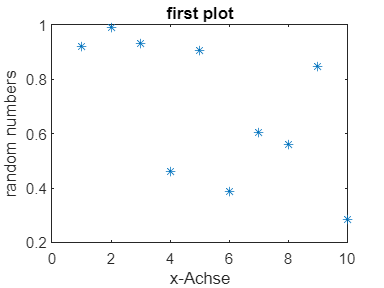

x = 1:10;
y = rand(10,1);
plot(x,y,'*')
xlabel('x-Achse')
ylabel('random numbers')
title('first plot')

**Exercise**: Plot a linear function with y = m*x + c, where m = 2 and c = 1

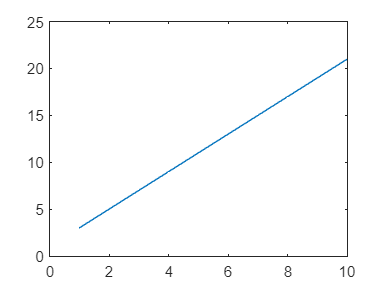

y = 2.* x + 1;
plot(x,y)

% your code


**New**: Importing of data 

- Using Import Data App

- Using one of many import functions, we are using the **readtable**(data) function

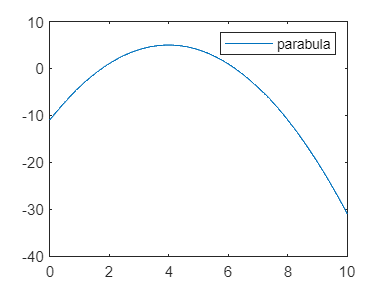

data = readtable('exampleData.csv'); % imports data as table
data = table2array(data); % data is turned numeric
xData = data(:,1);
yData = data(:,2);
plot(xData,yData)
% plot(data(:,1),data(:,2))
legend('parabula')

Also **new**: Accessing of data of multidimensional arrays 

**New**: **max**(data), **min**(data) those functions will find the Minimum or Maximum of a data set

Exercsie: Find the Minimum and the Maximum of the y-data set

- Advanced: also find the Index of the Minimum/Maximum (hint look for [`[M,I] = min(``___``)`](https://de.mathworks.com/help/matlab/ref/min.html#d123e931907)` )`

% your code


**Little excurse exercise: **Create an extra Matlab file and import the data from the exercise before and run it.

- (Together) Lets have a look at the PLOTS application of Matlab

- (Together) Lets also have a look at the Figure Palette

- Installation of the curve fitting toolbox

- Using the curve fitting toolbox

## Section: Functions and Fitting

**New**: creation of mathematical functions. This is important for fitting into data. The goal is to rebuild this function: f(x) = a * (x-b)^2 + c

data = readtable('exampleData.csv'); % imports data as table
data = table2array(data); % data is turned numeric
xData = data(:,1);
yData = data(:,2);

fun = @(x, xdata) x(1).*(xdata - x(2)).^2 + x(3) %symbolic function

fun = function_handle with value:
    @(x,xdata)x(1).*(xdata-x(2)).^2+x(3)


x = [1 2 3];
plot(xData, fun(x,xData))


**New**: First fit method `x = lsqcurvefit(fun,x0,xdata,ydata) ``this method solves non linear equation with a least square algorythm`

Link: [Solve nonlinear curve-fitting (data-fitting) problems in least-squares sense - MATLAB lsqcurvefit - MathWorks Deutschland](https://de.mathworks.com/help/optim/ug/lsqcurvefit.html)

x0 = [-1 1 1]; %initial values
x = lsqcurvefit(fun,x0,xData,yData)


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


x =    -1.0000    4.0000    5.0000


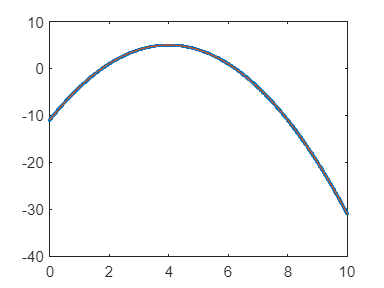


plot(data(:,1),data(:,2),'.')
hold on
plot(xData, fun(x,xData))